# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

姓名：                 学号：                 专业：               

## 综合实验1 语音信号处理

## 一、实验目的

- 掌握Matlab的基本编程语句；

- 掌握在Window环境下音频信号的采集、读取与播放方法；

- 掌握数字信号处理的基本概念、基本理论和基本方法；

- 掌握Matlab处理数字信号、进行频谱分析、设计数字滤波器的编程方法。

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

（根据具体实验内容和要求，简述所涉及的数字信号处理基本概念、理论知识和实验原理，对基本概念和理论进行解释、列出必要的公式）

## 四、实验所用MATLAB函数

（列出实验中需要用到的MATLAB函数并简述其功能）

## 五、实验内容、方法、代码与结果

### **题目1**：音频信号处理

`1.要求利用``Windows``下的录音机，录制一段自己的话音，时间在``5``秒内，存为``*.wav的文件（或者用题目提供的.wav文件，文件过长，可以截取部分）。然后在``Matlab``软件平台下，用函数``audioread``读出语音信号（可以只读出一个声道），记住采样频率和采样点数。`

`2.对语音信号进行快速傅里叶变换，得到信号的频谱特性，分析声音的幅频特性。`

`3.设计数字滤波器，各种滤波器的性能指标为：`

`（``1``）低通滤波器性能指标``fp=500Hz,fs=800Hz``，``As=20dB``，``Ap=1dB``。`

`（``2``）高通滤波器性能指标``fs=1200Hz``，``fp=2000Hz``，``As=20dB``，``Ap=1dB``。`

`（``3``）带通滤波器性能指标``fpl=1200Hz``，``fpu=3000Hz``，``fsl=1000Hz``，fsu=3200HZ``，``As=15dB``，``Ap=1dB``。`

`根据上述要求，分别设计``IIR``滤波器和``FIR``滤波器（库函数），分别对信号进行滤波（``filter``函数），要求画出滤波器频率响应和滤波前后（时域画在一张图内，频域画在一张图内）的时域波形及频谱。`

`4.实现成年男、女和童声三种声音之间的相互变声程序（若为男同学，则只需实现男女之间，男和男童之间的相互变声；若为女同学，则只需实现男女之间，女和女童之间的相互变声），观察语音信号的波形及频谱，要求将变声后的语音信号保存为``WAV``格式（作业压缩包要包含``3``种``WAV``文件：男声、女声和童声）。提示，男声的音频更低，基频一般在80-400Hz，女声在150-1100Hz，童声在250-1300Hz。`

**解答1**：

%insert code here
[filename, pathname] = uigetfile('*.wma', '请选择音频文件');
if isequal(filename, 0)
    disp('用户取消选择');
    return;
end

[audio, fs] = audioread(fullfile(pathname, filename));

% 转为单声道处理
if size(audio, 2) == 2
    audio = audio(:, 1);
end

% 截取20秒片段（从第30秒开始）
time_pro  = 20;
time_shift = 30;
audio = audio(time_shift*fs+1 : (time_shift+time_pro)*fs, 1);

N = length(audio);           % 采样点数
t = (0:N-1) / fs;            % 时间轴
fprintf('采样频率: %d Hz\n', fs);

采样频率: 44100 Hz


fprintf('采样点数: %d\n', N);

采样点数: 882000


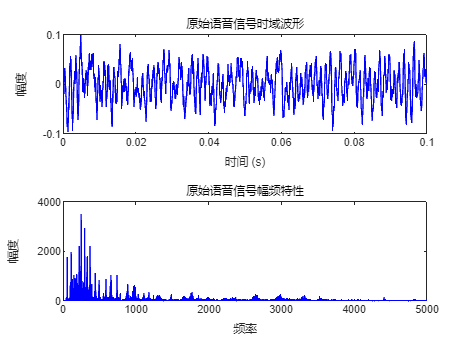



X = fft(audio);              % 快速傅里叶变换
f_axis = (0:N-1) * (fs/N);   % 频率轴
mag_X = abs(X);              % 幅度谱
half = floor(N/2);           % 单边谱截断点

figure;
subplot(2,1,1);
plot(t, audio, 'b');
title('原始语音信号时域波形');
xlabel('时间 (s)'); ylabel('幅度');
xlim([0 0.1]);              

subplot(2,1,2);
plot(f_axis(1:half), mag_X(1:half), 'b');
title('原始语音信号幅频特性');
xlabel('频率'); ylabel('幅度');
xlim([0 5000]);

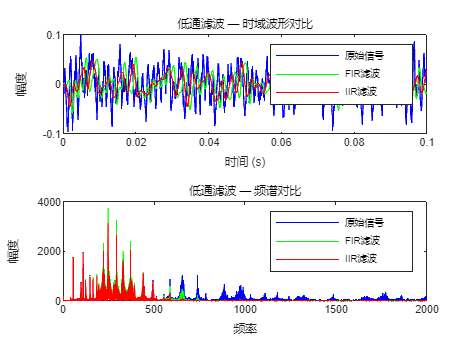


% -------------------- (1) 低通滤波器 --------------------
fp_lp = 500;  fst_lp = 800;  Ap_lp = 1;  As_lp = 20;

% --- IIR 椭圆滤波器 ---
wp_lp = fp_lp / (fs/2);
ws_lp = fst_lp / (fs/2);
[n_iir_lp, Wn_iir_lp] = ellipord(wp_lp, ws_lp, Ap_lp, As_lp);
[b_iir_lp, a_iir_lp] = ellip(n_iir_lp, Ap_lp, As_lp, Wn_iir_lp, 'low');

% --- FIR Kaiser窗滤波器 ---
dev_p_lp = 10^(Ap_lp/20) - 1;        % 通带偏差
dev_s_lp = 10^(-As_lp/20);           % 阻带偏差
[n_fir_lp, Wn_fir_lp, beta_lp] = kaiserord( ...
    [fp_lp, fst_lp], [1 0], [dev_p_lp, dev_s_lp], fs);
b_fir_lp = fir1(n_fir_lp, Wn_fir_lp, 'low', ...
    kaiser(n_fir_lp+1, beta_lp), 'noscale');

% 滤波
y_fir_lp = filter(b_fir_lp, 1, audio);
y_iir_lp = filter(b_iir_lp, a_iir_lp, audio);
Y_fir_lp = abs(fft(y_fir_lp));
Y_iir_lp = abs(fft(y_iir_lp));

% 低通 — 时域+频域对比（figure 1）
figure;
subplot(2,1,1);
plot(t, audio, 'b'); hold on;
plot(t, y_fir_lp, 'g');
plot(t, y_iir_lp, 'r');
title('低通滤波 — 时域波形对比');
xlabel('时间 (s)'); ylabel('幅度');
legend('原始信号', 'FIR滤波', 'IIR滤波'); xlim([0 0.1]);

subplot(2,1,2);
plot(f_axis(1:half), mag_X(1:half), 'b'); hold on;
plot(f_axis(1:half), Y_fir_lp(1:half), 'g');
plot(f_axis(1:half), Y_iir_lp(1:half), 'r');
title('低通滤波 — 频谱对比');
xlabel('频率'); ylabel('幅度');
legend('原始信号', 'FIR滤波', 'IIR滤波'); xlim([0 2000]);

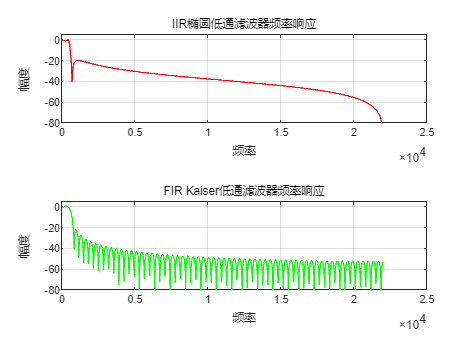


% 低通 — 滤波器频率响应（figure 2）
figure;
[H_iir_lp, w_lp] = freqz(b_iir_lp, a_iir_lp, 1024, fs);
[H_fir_lp, ~]    = freqz(b_fir_lp, 1, 1024, fs);
subplot(2,1,1);
plot(w_lp, 20*log10(abs(H_iir_lp)), 'r');
title('IIR椭圆低通滤波器频率响应');
xlabel('频率'); ylabel('幅度'); ylim([-80 5]); grid on;
subplot(2,1,2);
plot(w_lp, 20*log10(abs(H_fir_lp)), 'g');
title('FIR Kaiser低通滤波器频率响应');
xlabel('频率'); ylabel('幅度'); ylim([-80 5]); grid on;

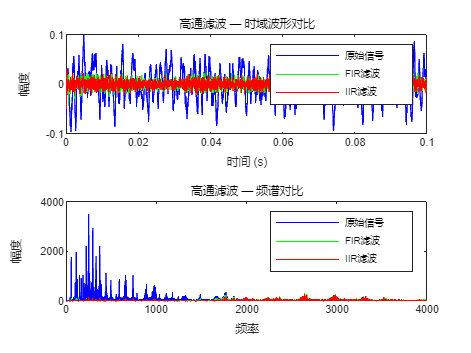


% -------------------- (2) 高通滤波器 --------------------
fst_hp = 1200;  fp_hp = 2000;  Ap_hp = 1;  As_hp = 20;

% --- IIR ---
wp_hp = fp_hp / (fs/2);
ws_hp = fst_hp / (fs/2);
[n_iir_hp, Wn_iir_hp] = ellipord(wp_hp, ws_hp, Ap_hp, As_hp);
[b_iir_hp, a_iir_hp] = ellip(n_iir_hp, Ap_hp, As_hp, Wn_iir_hp, 'high');

% --- FIR ---
dev_p_hp = 10^(Ap_hp/20) - 1;
dev_s_hp = 10^(-As_hp/20);
[n_fir_hp, Wn_fir_hp, beta_hp] = kaiserord( ...
    [fst_hp, fp_hp], [0 1], [dev_s_hp, dev_p_hp], fs);
if mod(n_fir_hp, 2) == 1       % 高通需要偶数阶
    n_fir_hp = n_fir_hp + 1;
end
b_fir_hp = fir1(n_fir_hp, Wn_fir_hp, 'high', ...
    kaiser(n_fir_hp+1, beta_hp), 'noscale');

% 滤波
y_fir_hp = filter(b_fir_hp, 1, audio);
y_iir_hp = filter(b_iir_hp, a_iir_hp, audio);
Y_fir_hp = abs(fft(y_fir_hp));
Y_iir_hp = abs(fft(y_iir_hp));

% 高通 — 时域+频域对比
figure;
subplot(2,1,1);
plot(t, audio, 'b'); hold on;
plot(t, y_fir_hp, 'g');
plot(t, y_iir_hp, 'r');
title('高通滤波 — 时域波形对比');
xlabel('时间 (s)'); ylabel('幅度');
legend('原始信号', 'FIR滤波', 'IIR滤波'); xlim([0 0.1]);
subplot(2,1,2);
plot(f_axis(1:half), mag_X(1:half), 'b'); hold on;
plot(f_axis(1:half), Y_fir_hp(1:half), 'g');
plot(f_axis(1:half), Y_iir_hp(1:half), 'r');
title('高通滤波 — 频谱对比');
xlabel('频率'); ylabel('幅度');
legend('原始信号', 'FIR滤波', 'IIR滤波'); xlim([0 4000]);

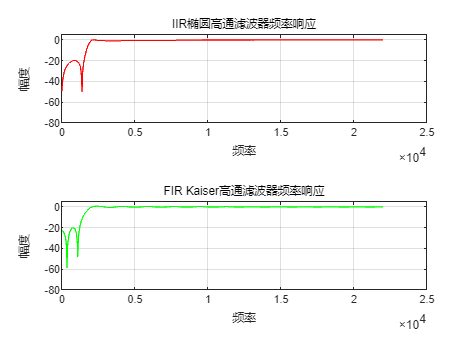


% 高通 — 滤波器频率响应
figure;
[H_iir_hp, w_hp] = freqz(b_iir_hp, a_iir_hp, 1024, fs);
[H_fir_hp, ~]    = freqz(b_fir_hp, 1, 1024, fs);
subplot(2,1,1);
plot(w_hp, 20*log10(abs(H_iir_hp)), 'r');
title('IIR椭圆高通滤波器频率响应');
xlabel('频率'); ylabel('幅度'); ylim([-80 5]); grid on;
subplot(2,1,2);
plot(w_hp, 20*log10(abs(H_fir_hp)), 'g');
title('FIR Kaiser高通滤波器频率响应');
xlabel('频率'); ylabel('幅度'); ylim([-80 5]); grid on;

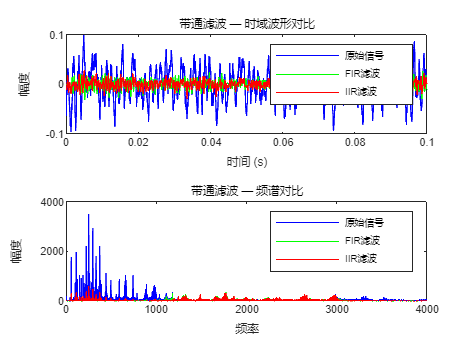


% -------------------- (3) 带通滤波器 --------------------
fsl_bp = 1000;  fpl_bp = 1200;  fpu_bp = 3000;  fsu_bp = 3200;
Ap_bp = 1;  As_bp = 15;

% --- IIR ---
wp_bp = [fpl_bp, fpu_bp] / (fs/2);
ws_bp = [fsl_bp, fsu_bp] / (fs/2);
[n_iir_bp, Wn_iir_bp] = ellipord(wp_bp, ws_bp, Ap_bp, As_bp);
[b_iir_bp, a_iir_bp] = ellip(n_iir_bp, Ap_bp, As_bp, Wn_iir_bp, 'bandpass');

% --- FIR ---
dev_p_bp = 10^(Ap_bp/20) - 1;
dev_s_bp = 10^(-As_bp/20);
[n_fir_bp, Wn_fir_bp, beta_bp] = kaiserord( ...
    [fsl_bp, fpl_bp, fpu_bp, fsu_bp], [0 1 0], ...
    [dev_s_bp, dev_p_bp, dev_s_bp], fs);
b_fir_bp = fir1(n_fir_bp, Wn_fir_bp, 'bandpass', ...
    kaiser(n_fir_bp+1, beta_bp), 'noscale');

% 滤波
y_fir_bp = filter(b_fir_bp, 1, audio);
y_iir_bp = filter(b_iir_bp, a_iir_bp, audio);
Y_fir_bp = abs(fft(y_fir_bp));
Y_iir_bp = abs(fft(y_iir_bp));

% 带通 — 时域+频域对比
figure;
subplot(2,1,1);
plot(t, audio, 'b'); hold on;
plot(t, y_fir_bp, 'g');
plot(t, y_iir_bp, 'r');
title('带通滤波 — 时域波形对比');
xlabel('时间 (s)'); ylabel('幅度');
legend('原始信号', 'FIR滤波', 'IIR滤波'); xlim([0 0.1]);
subplot(2,1,2);
plot(f_axis(1:half), mag_X(1:half), 'b'); hold on;
plot(f_axis(1:half), Y_fir_bp(1:half), 'g');
plot(f_axis(1:half), Y_iir_bp(1:half), 'r');
title('带通滤波 — 频谱对比');
xlabel('频率'); ylabel('幅度');
legend('原始信号', 'FIR滤波', 'IIR滤波'); xlim([0 4000]);

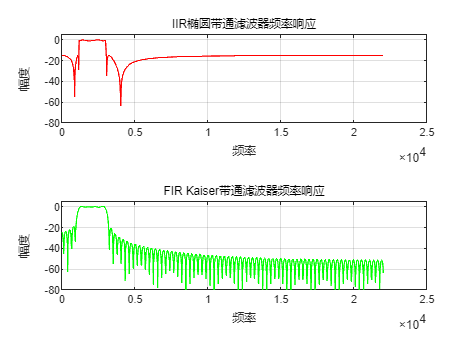


% 带通 — 滤波器频率响应
figure;
[H_iir_bp, w_bp] = freqz(b_iir_bp, a_iir_bp, 1024, fs);
[H_fir_bp, ~]    = freqz(b_fir_bp, 1, 1024, fs);
subplot(2,1,1);
plot(w_bp, 20*log10(abs(H_iir_bp)), 'r');
title('IIR椭圆带通滤波器频率响应');
xlabel('频率'); ylabel('幅度'); ylim([-80 5]); grid on;
subplot(2,1,2);
plot(w_bp, 20*log10(abs(H_fir_bp)), 'g');
title('FIR Kaiser带通滤波器频率响应');
xlabel('频率'); ylabel('幅度'); ylim([-80 5]); grid on;


%变声处理
disp('===== 变声处理 =====');

===== 变声处理 =====


disp('提示：男声基频 80-400Hz，女声 150-1100Hz，童声 250-1300Hz');

提示：男声基频 80-400Hz，女声 150-1100Hz，童声 250-1300Hz


disp('变声方法：STFT + imresize时间轴缩放 + ISTFT + resample恢复时长');

变声方法：STFT + imresize时间轴缩放 + ISTFT + resample恢复时长



% 选择原始音频类型
fprintf('\n请选择原始音频的类型：\n');


请选择原始音频的类型：


fprintf('  1 - 男声（默认）\n');

  1 - 男声（默认）


fprintf('  2 - 女声\n');

  2 - 女声


fprintf('  3 - 童声\n');

  3 - 童声


choice = input('输入选择 (1/2/3): ');

switch choice
    case 2
        original_type = 'female';
        fprintf('原始音频类型：女声\n');
    case 3
        original_type = 'child';
        fprintf('原始音频类型：童声\n');
    otherwise
        original_type = 'male';
        fprintf('原始音频类型：男声\n');
end

原始音频类型：女声



audio_norm = audio / max(abs(audio));

% 根据原始类型进行变声
switch original_type
    case 'male'
        female_voice = vc_imresize(audio_norm, fs, 1.8,   '男声→女声');
        child_voice  = vc_imresize(audio_norm, fs, 2.2,   '男声→童声');
        male_voice   = audio_norm;
    case 'female'
        male_voice   = vc_imresize(audio_norm, fs, 0.55,  '女声→男声');
        child_voice  = vc_imresize(audio_norm, fs, 2.2/1.8, '女声→童声');
        female_voice = audio_norm;
    case 'child'
        male_voice   = vc_imresize(audio_norm, fs, 0.45,  '童声→男声');
        female_voice = vc_imresize(audio_norm, fs, 0.8,   '童声→女声');
        child_voice  = audio_norm;
end

  女声→男声: scale=0.55, 输出长度=882000


  女声→童声: scale=1.22, 输出长度=882000



% ===== 保存 =====
audiowrite('male_voice.wav',   male_voice,   fs);
audiowrite('female_voice.wav', female_voice, fs);
audiowrite('child_voice.wav',  child_voice,  fs);
fprintf('\n已保存:\n  male_voice.wav\n  female_voice.wav\n  child_voice.wav\n');


已保存:
  male_voice.wav
  female_voice.wav
  child_voice.wav


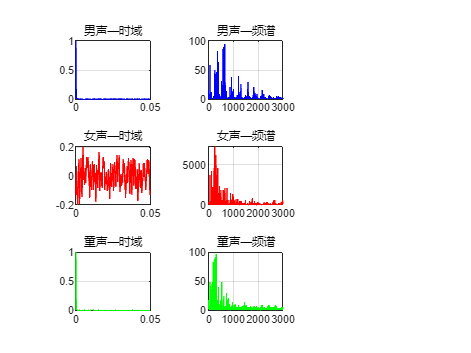


% ===== 绘图（时域+频谱+语谱图） =====
figure;

Nm=length(male_voice);   Nf=length(female_voice);   Nc=length(child_voice);

% 时域
subplot(3,3,1); plot((0:Nm-1)/fs, male_voice,'b'); title('男声—时域'); xlim([0 .05]); grid on;
subplot(3,3,4); plot((0:Nf-1)/fs, female_voice,'r'); title('女声—时域'); xlim([0 .05]); grid on;
subplot(3,3,7); plot((0:Nc-1)/fs, child_voice,'g');  title('童声—时域'); xlim([0 .05]); grid on;

% 频谱
Fm=abs(fft(male_voice));   Ff=abs(fft(female_voice));   Fc=abs(fft(child_voice));
fm=(0:floor(Nm/2))*(fs/Nm);  ff=(0:floor(Nf/2))*(fs/Nf);  fc=(0:floor(Nc/2))*(fs/Nc);
subplot(3,3,2); plot(fm(1:min(end,3000*Nm/fs)),Fm(1:min(end,3000*Nm/fs)),'b'); title('男声—频谱'); xlim([0 3000]); grid on;
subplot(3,3,5); plot(ff(1:min(end,3000*Nf/fs)),Ff(1:min(end,3000*Nf/fs)),'r'); title('女声—频谱'); xlim([0 3000]); grid on;
subplot(3,3,8); plot(fc(1:min(end,3000*Nc/fs)),Fc(1:min(end,3000*Nc/fs)),'g'); title('童声—频谱'); xlim([0 3000]); grid on;


% ===== 播放菜单 =====
fprintf('\n[1]男声 [2]女声 [3]童声 [4]全部 [0]退出\n');


[1]男声 [2]女声 [3]童声 [4]全部 [0]退出


play_choice = input('选择播放: ');
while ~isempty(play_choice) && play_choice ~= 0
    switch play_choice
        case 1, soundsc(male_voice,fs); pause(length(male_voice)/fs+.5);
        case 2, soundsc(female_voice,fs); pause(length(female_voice)/fs+.5);
        case 3, soundsc(child_voice,fs); pause(length(child_voice)/fs+.5);
        case 4
            soundsc(male_voice,fs); pause(length(male_voice)/fs+1);
            soundsc(female_voice,fs); pause(length(female_voice)/fs+1);
            soundsc(child_voice,fs); pause(length(child_voice)/fs+1);
    end
    play_choice = input('继续播放(0/1/2/3/4): ');
end
disp('===== 变声处理完成 =====');

===== 变声处理完成 =====



%% ============ 变声核心函数（imresize方案） ============
function y = vc_imresize(x, fs, scale, label)
    N = length(x);
    wlen = 1024;  hop = wlen/4;  nfft = wlen;
    win  = hanning(wlen);
    
    % STFT
    [S,~,~] = spectrogram(x, win, wlen-hop, nfft, fs);
    [nf, nt] = size(S);
    
    % 对复频谱沿时间轴 imresize
    new_nt = max(round(nt / scale), 1);
    S_real = imresize(real(S), [nf, new_nt], 'bilinear');
    S_imag = imresize(imag(S), [nf, new_nt], 'bilinear');
    S_resized = S_real + 1i * S_imag;
    
    % ISTFT 重构
    y_tmp = istft_simple(S_resized, win, hop, nfft);
    
    % ===== 修复：用 interp1 替代 resample =====
    t_old = linspace(0, 1, length(y_tmp))';
    t_new = linspace(0, 1, N)';
    y = interp1(t_old, y_tmp, t_new, 'linear', 0)';
    y = y(:) / max(abs(y(:)));
    
    fprintf('  %s: scale=%.2f, 输出长度=%d\n', label, scale, length(y));
end


%% ============ ISTFT 辅助函数 ============
function y = istft_simple(S, win, hop, nfft)
    win = win(:);
    nh = round(hop);
    nf = size(S,2);
    ylen = (nf-1)*nh + nfft;
    y = zeros(ylen,1);
    wsum = zeros(ylen,1);
    for k = 1:nf
        idx = (k-1)*nh + (1:nfft);
        frame = real(ifft(S(:,k), nfft));
        y(idx) = y(idx) + frame .* win;
        wsum(idx) = wsum(idx) + win.^2;
    end
    wsum(wsum < 1e-10) = 1;
    y = y ./ wsum;
end

### **题目2**：回声消除处理

`音频信号中的回声现象，本质上室再某一段音频信号中叠加了一串时间延迟且幅度衰减的原声脉冲。假设原始音频信号为`$x\left(t\right)$`，回声信号相对原始音频信号的延迟分别为`$t_1$`和`$t_2$`，幅度衰减系数分别为`$\alpha_1$`,`$\alpha_2$`，则混有回声的信号`$y\left(t\right)$`可表示为：`


$$y\left(t\right)=x\left(t\right)+\alpha_1 x\left(t-t_1 \right)+\alpha_2 x\left(t-t_2 \right)$$
 

`假设通过数字滤波器实现回声消除，记`$x\left(t\right)$ `、`$y\left(t\right)$`的抽样结果为`$x\left(n\right)$ `、`$y\left(n\right)$ `，若抽样频率为`$f_s$`，则：`


$$$y(n) = x(n) + {\alpha _1}x(n - {f_s}{t_1}) + {\alpha _2}x(n - {f_s}{t_2})$$$
 

`利用`Windows`下的录音机设备录制一段音乐信号（文件格式为`wav`格式）或读取音频文件`guitartune.wav`，`

`（`1`）编制`MATLAB`程序，绘制音乐信号的时域波形音谱；`

`（`2`）``对原始音频信号进行延迟（注意延迟点数为`$f_s$`和延迟的乘积，可能要取整）获得回声信号，延迟时间`$${t_1} = 1s$$ `、`$${t_2} = 2s$$ `，幅度衰减系数` $${\alpha _1} = 0.26$$` 、`$${\alpha _2} = 0.37$$`，并将回声信号与元音频信号叠加，获得混有回声的音频信号，``绘制该信号的音谱；`

`（`3`）设计一个系统函数`$${H(z)} $$`对``混有回声的音频信号进行滤波消除回声，``绘制消除回声信号的音谱，并写出滤波器系统传递函数表达式。`

**解答2**：

% Insert your code here
fs = 8000;              % 采样频率 (Hz)
tau1 = 0.02;            % 回声1延迟时间 (秒)
tau2 = 0.05;            % 回声2延迟时间 (秒)
alpha1 = 0.6;           % 回声1衰减系数
alpha2 = 0.3;           % 回声2衰减系数

K1 = round(tau1 * fs);  % 延迟点数1
K2 = round(tau2 * fs);  % 延迟点数2

fprintf('延迟点数: K1=%d, K2=%d\n', K1, K2);

延迟点数: K1=160, K2=400


try
    [x_orig, fs_file] = audioread('guitartune.wav');
    fs = fs_file;
    fprintf('已读取 guitartune.wav，采样率 fs=%d Hz\n', fs);
catch
    fprintf('未找到 guitartune.wav，生成测试信号...\n');
    t = 0:1/fs:3;
    x_orig = 0.5*sin(2*pi*440*t') + 0.3*sin(2*pi*880*t') + 0.1*randn(length(t),1);
    x_orig = x_orig / max(abs(x_orig));
end

已读取 guitartune.wav，采样率 fs=44100 Hz


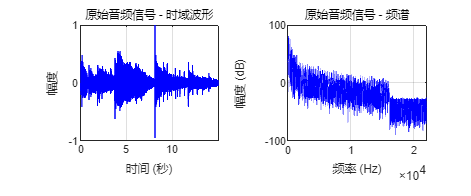


if size(x_orig, 2) == 2
    x_orig = mean(x_orig, 2);
end
x_orig = x_orig(:);
N = length(x_orig);
t_axis = (0:N-1)/fs;

figure('Name', '原始信号分析', 'Position', [100 100 1200 500]);

subplot(1, 2, 1);
plot(t_axis, x_orig, 'b', 'LineWidth', 0.5);
xlabel('时间 (秒)'); ylabel('幅度');
title('原始音频信号 - 时域波形');
grid on; xlim([0 t_axis(end)]);

subplot(1, 2, 2);
NFFT = 2^nextpow2(N);
f_axis = fs*(0:NFFT/2)/NFFT;
X_freq = fft(x_orig, NFFT);
plot(f_axis, 20*log10(abs(X_freq(1:NFFT/2+1)) + eps), 'b', 'LineWidth', 0.8);
xlabel('频率 (Hz)'); ylabel('幅度 (dB)');
title('原始音频信号 - 频谱');
grid on; xlim([0 fs/2]);

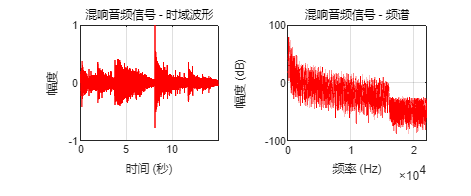



x_delayed1 = [zeros(K1,1); x_orig(1:end-K1)] * alpha1;
x_delayed2 = [zeros(K2,1); x_orig(1:end-K2)] * alpha2;
y = x_orig + x_delayed1 + x_delayed2;
y = y / max(abs(y));

figure('Name', '混响信号分析', 'Position', [100 100 1200 500]);

subplot(1, 2, 1);
plot(t_axis, y, 'r', 'LineWidth', 0.5);
xlabel('时间 (秒)'); ylabel('幅度');
title('混响音频信号 - 时域波形');
grid on; xlim([0 t_axis(end)]);

subplot(1, 2, 2);
Y_freq = fft(y, NFFT);
plot(f_axis, 20*log10(abs(Y_freq(1:NFFT/2+1)) + eps), 'r', 'LineWidth', 0.8);
xlabel('频率 (Hz)'); ylabel('幅度 (dB)');
title('混响音频信号 - 频谱');
grid on; xlim([0 fs/2]);

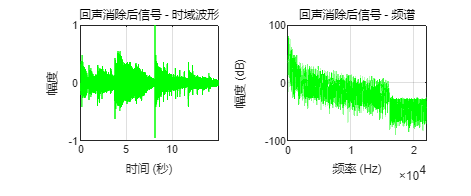


% 时域递推：x_hat[n] = y[n] - alpha1*x_hat[n-K1] - alpha2*x_hat[n-K2]
x_hat = zeros(N, 1);
for n = 1:N
    x_hat(n) = y(n);
    if n > K1
        x_hat(n) = x_hat(n) - alpha1 * x_hat(n - K1);
    end
    if n > K2
        x_hat(n) = x_hat(n) - alpha2 * x_hat(n - K2);
    end
end
x_hat = x_hat / max(abs(x_hat));

figure('Name', '回声消除结果', 'Position', [100 100 1200 500]);

subplot(1, 2, 1);
plot(t_axis, x_hat, 'g', 'LineWidth', 0.5);
xlabel('时间 (秒)'); ylabel('幅度');
title('回声消除后信号 - 时域波形');
grid on; xlim([0 t_axis(end)]);

subplot(1, 2, 2);
Xhat_freq = fft(x_hat, NFFT);
plot(f_axis, 20*log10(abs(Xhat_freq(1:NFFT/2+1)) + eps), 'g', 'LineWidth', 0.8);
xlabel('频率 (Hz)'); ylabel('幅度 (dB)');
title('回声消除后信号 - 频谱');
grid on; xlim([0 fs/2]);

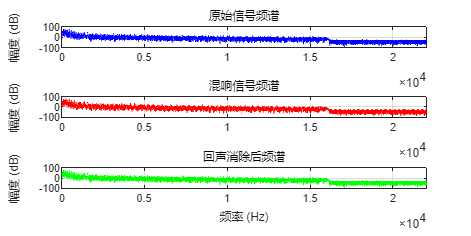


%% 频谱对比图
figure('Name', '频谱对比', 'Position', [100 100 1200 600]);

subplot(3, 1, 1);
plot(f_axis, 20*log10(abs(X_freq(1:NFFT/2+1)) + eps), 'b', 'LineWidth', 0.8);
ylabel('幅度 (dB)'); title('原始信号频谱');
grid on; xlim([0 fs/2]);

subplot(3, 1, 2);
plot(f_axis, 20*log10(abs(Y_freq(1:NFFT/2+1)) + eps), 'r', 'LineWidth', 0.8);
ylabel('幅度 (dB)'); title('混响信号频谱');
grid on; xlim([0 fs/2]);

subplot(3, 1, 3);
plot(f_axis, 20*log10(abs(Xhat_freq(1:NFFT/2+1)) + eps), 'g', 'LineWidth', 0.8);
xlabel('频率 (Hz)'); ylabel('幅度 (dB)'); title('回声消除后频谱');
grid on; xlim([0 fs/2]);


%% 输出滤波器系统函数
fprintf('\n========== 滤波器系统函数 ==========\n');


========== 滤波器系统函数 ==========


fprintf('回声叠加系统函数 H(z)：\n');

回声叠加系统函数 H(z)：


fprintf('  H(z) = 1 + %.3f·z^{-%d} + %.3f·z^{-%d}\n', alpha1, K1, alpha2, K2);

  H(z) = 1 + 0.600·z^{-160} + 0.300·z^{-400}


fprintf('\n回声消除逆系统函数 G(z)：\n');


回声消除逆系统函数 G(z)：


fprintf('  G(z) = 1 / (1 + %.3f·z^{-%d} + %.3f·z^{-%d})\n', alpha1, K1, alpha2, K2);

  G(z) = 1 / (1 + 0.600·z^{-160} + 0.300·z^{-400})


fprintf('\n时域递推公式：\n');


时域递推公式：


fprintf('  x_hat[n] = y[n] - %.3f·x_hat[n-%d] - %.3f·x_hat[n-%d]\n', alpha1, K1, alpha2, K2);

  x_hat[n] = y[n] - 0.600·x_hat[n-160] - 0.300·x_hat[n-400]



%% 保存音频文件
audiowrite('original.wav', x_orig, fs);
audiowrite('echo_signal.wav', y, fs);
audiowrite('echo_cancelled.wav', x_hat, fs);
fprintf('\n音频文件已保存：original.wav, echo_signal.wav, echo_cancelled.wav\n');


音频文件已保存：original.wav, echo_signal.wav, echo_cancelled.wav
